%{
Program to denoise images using low rank completion methods
Harsh Shah and Pranava Singhal 
%}

addpath '.\MMread';
rng(73);

[video, audio] = mmread('.\data\akiyo_cif.y4m');

% reading the meta data and frames of the video 
H = video.height;
W = video.width;
K = 50;
num_channels = 3;
frames = zeros(H, W, num_channels, K);
for i=1:1:K
    frames(:, :, :, i) = uint8(video.frames(i).cdata);
end
frames = uint8(frames);

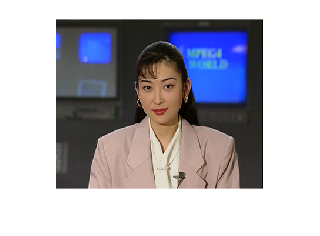

imshow(frames(:, :, :, 1))

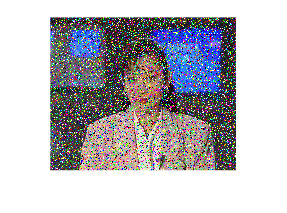

% noise generation
sigma = 20; 
kappa = 5;
mu = 0;
s = 0.3;
groundTruth = frames(:, :, :, 1);
imshow(noisify(groundTruth, sigma, mu, kappa, s));

noisy_video = zeros(H,W,num_channels,K);
for T = 1:K
    noisy_video(:,:,:,T) = noisify(frames(:,:,:,T), sigma, mu, kappa, s);
end

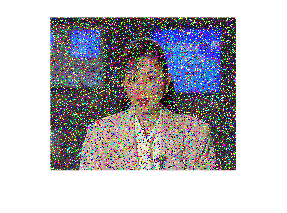

imshow(noisy_video(:,:,:,10))

% denoising using adaptive median filtering
[omega , denoised_frames] = ramf(noisy_video(:,:,:,1));

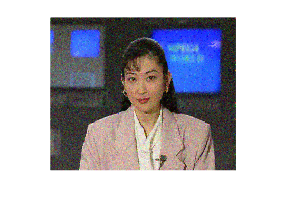

imshow(denoised_frames(:,:,:,1));

% soft_shrinkage testing
soft_shrinkage(x, 2)

% nuclear norm testing
nucnorm = norm(eig(x),1);

function for adding noise to a given image

groundTruth: uint8 

function result = noisify(groundTruth, sigma, mu, kappa, s)
    H = size(groundTruth, 1);
    W = size(groundTruth, 2);
    num_channels = size(groundTruth, 3);
    gaussian_noise = normrnd(mu, sigma, H, W, num_channels);
    poisson_noise = poissrnd(kappa, H, W, num_channels);
    
    result = double(groundTruth) + gaussian_noise + poisson_noise;
    
    result(result > 255) = 255;
    result(result < 0) = 0;

    for i=1:H
        for j=1:W
            if rand() < s
                result(i, j, :) = noisy_pixel(num_channels);
            end
        end
    end
    result = result/255;
end

% functin for generating salt and pepper noise
function pixel = noisy_pixel(num_channels)
    pixel = zeros(1, 1, 3);
    for i=1:num_channels
        if rand() < 0.5
            pixel(1, 1, i) = 0;
        else
            pixel(1, 1, i) = 255;
        end
    end
end

% function for soft shrinkage 
function result = soft_shrinkage(A, tau)
    [U, S, V] = svd(A);
    S(S>0) = S(S>0)-tau;
    S(S<0) = 0;
    result = U*S*V';
end

function patches = generatePatches_nonoverlap(image, patch_r, patch_c) 
    rows = size(image, 1);
    columns = size(image, 2);
    wholeBlockRows = floor(rows / patch_r);
    wholeBlockCols = floor(columns / patch_c);
    trailing_rows = rows - wholeBlockRows * patch_r;
    trailing_cols = columns - wholeBlockCols * patch_c;
    image3d_cell = mat2cell( image, [ patch_r * ones(1, wholeBlockRows), trailing_rows], [patch_c * ones(1, wholeBlockCols), trailing_cols], size(image, 3) );
    if trailing_rows == 0 && trailing_cols == 0
      patches = cat( ndims(image)+1, image3d_cell{1:end-1,1:end-1} );
    else
      display("Image size and patch size not compatible");    
    end
end

% function to generate overlapping patches
function patches = generatePatches_overlapping(image, patch_dim, stride)
    height = size(image, 1);
    width = size(image, 2);
    T = size(image, 3);
    assert(rem(height-patch_dim, stride) == 0);
    assert(rem(width-patch_dim, stride) == 0);
    blocks_x = (width-patch_dim)/stride+1;
    blocks_y = (height-patch_dim)/stride+1;
    
    patches = zeros(patch_dim, patch_dim, T, blocks_x*blocks_y);

    for i=1:blocks_x
        for j=1:blocks_y
            patch = image((j-1)*stride+1 : patch_dim+(j-1)*stride,(i-1)*stride+1 : patch_dim+(i-1)*stride, :);
            patches(:, :, :, (i-1)*blocks_y+j) = patch;
        end
    end
end

% for stiching the non-overlapping patches
function result = imageReconstruction_non_overlapping(all_patches, x_patches, y_patches)
    all_patches_size = size(all_patches);
    num_patches = all_patches_size(1);
    patch_size = all_patches_size(2);
    T = all_patches_size(4);
    assert(num_patches*patch_size*patch_size*T == y_patches*patch_size*x_patches*patch_size*T);
    reconstruction = zeros(y_patches*patch_size, x_patches*patch_size, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*patch_size+1:j*patch_size, (i-1)*patch_size+1:i*patch_size, :) = all_patches((i-1)*y_patches + j, :, :, :);
        end
    end
    result = reconstruction;
end

% function to stitch image from overlapping patches
function result = imageReconstruction_overlapping(all_patches, x_patches, y_patches, stride)
    all_patches_size = size(all_patches);
    patch_dim = all_patches_size(2);
    T = all_patches_size(4);
    height = patch_dim + stride*(y_patches-1);
    width = patch_dim + stride*(x_patches-1);
    
    reconstruction = zeros(height, width, T);
    count_mat = zeros(height, width, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + squeeze(all_patches((i-1)*y_patches + j, :, :, :));
            count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + ones(patch_dim, patch_dim, T);
        end
    end
    result = reconstruction./count_mat;  
end

% function for fixed point iteration(algorithm for matrix completion)
function result = fixed_point_iteration()

end

% function to reduce noise for patch matching
function result = level1_noise_reduction(all_patches)
    
end


% function for getting matching patches using cosine similarity
function result = patchmatching_cos_similarity(all_patches, reference_patch)
    
end


% function for getting matching patches using -three-step hierarchical search
function result = patchmatching_three_step(all_patches, reference_patch)
       
end

%{ 
function for adaptive median filter based on RAMF
function result = RAMF(raw_image)
Smax=9;
H = size(raw_image, 1);
W = size(raw_image, 2);
for i=1:H
    for j=1:W
        n = raw_image(i:i+2,j:j+2);
        Zmin=min(n(:));
        Zmax=max(n(:));
        Zmed=median(n(:));
        sx=3;
        sy=3;
        
        A1=Zmed-Zmin;
        A2=Zmed-Zmax;
        
        if (A1>0) && (A2<0)
          B1 = Zxy-Zmin;
          B2 = Zxy-Zmax;
          if (B1>0) && (B2<0)
                b(i:i+2,j:j+2) = n(i, j);
              break;
          else
               b(i:i+2,j:j+2) = Zmed;
              break;
          end 
        else 
          sx=sx+2;
          sy=sy+2;
          if (sx > Smax) && (sy > Smax)
              b(i:i+2,j:j+2) = n(i, j);
          end 
          end 
      end 
    end 
end
%}

function [omega, denoised_frames] = ramf(frames)
    H = size(frames, 1);
    W = size(frames, 2);
    num_channels = size(frames, 3);
    K = size(frames, 4);
    denoised_frames = double(zeros(size(frames)));
    omega = zeros(size(frames));
    for T = 1:K
        for i = 1:H
            for j = 1:W
                % stage 1 filtering
                for window_size = 3:2:floor(min(H/2,W/2))
                    delta = floor((window_size-1)/2);
                    pixels_in_window = zeros(window_size, window_size, num_channels);
                    for r = (i-delta):(i+delta)
                        for s = (j-delta):(j+delta)
                            if((r>= 1) && (s>=1) && (r<=H) && (s<= W))
                                pixels_in_window(r-i+delta+1,s-j+delta+1, :) = frames(r,s,:,T);
                            else
                                % locations outside frame
                                pixels_in_window(r-i+delta+1,s-j+delta+1, :) = -1;
                            end
                        end
                    end
                    
                    x_median = zeros([1,1,num_channels]);
                    x_min = zeros([1,1,num_channels]);
                    x_max = zeros([1,1,num_channels]);
                    
                    for channel = 1:num_channels
                        pixels_in_channel = pixels_in_window(:,:,channel);
                        valid_pixels = pixels_in_channel(pixels_in_channel >= 0);
                        x_median(:,:,channel) = median(valid_pixels(:));
                        x_min(:,:,channel) = min(valid_pixels(:));
                        x_max(:,:,channel) = max(valid_pixels(:));
                    end 
                    
                    T_minus = x_median - x_min;
                    T_plus = x_median - x_max;
                    if(sum(T_minus>0 & T_plus<0) == num_channels)
                        % stage 2 filtering
                        x_ij = frames(i,j,:,T);
                        %x_ij_squeeze = reshape(x_ij,[1,3]);
                                            
                        U_minus = x_ij - x_min;
                        U_plus = x_ij - x_max;

                        if(sum(U_minus>0 & U_plus<0) == num_channels)
                            denoised_frames(i,j,:,T) = x_ij;
                        else
                            denoised_frames(i,j,:,T) = x_median;
                            omega(i,j,:,T) = 1;
                        end
                        break;
                    end   
                end
    
            end
        end
    end  
end
